# Display_busVoltages.mlx

## This script will display precalculated analyses of grid parameters.

#### This script changes all interpretation parameters to LaTeX.

list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end

tic
folder_name = 'saved_outputs/'; %subfolder where data will be stored

system_name = 'ieee9'

system_name = 'ieee9'

run_number = 2

run_number = 2

lag = 10

lag = 10


tableName = strcat(folder_name, 'nominalValuesTable_', system_name, '_', ...
    string(run_number), '.csv')

tableName = "saved_outputs/nominalValuesTable_ieee9_2.csv"


nominalValuesTable = readtable(tableName)

nominalValuesTable = 1×11 table
    system_name    run_number    sampling_rate    downsampling_ratio    T      W      window_moving_ratio    bifurcation_limit    bifurcationIdx    lastIdx    convolutionMarginRatio
    ___________    __________    _____________    __________________    __    ____    ___________________    _________________    ______________    _______    ______________________

     {'ieee9'}         2             0.01                 1             10    1000           0.05                   0.9                8579          9657                0           


convolutonMarginRatio = nominalValuesTable.convolutionMarginRatio

convolutonMarginRatio = 0

convolutionMargin = convolutonMarginRatio*bifurcationIdx

convolutionMargin = 0


busesToPlot = 5;

sampling_rate = nominalValuesTable.sampling_rate

sampling_rate = 0.0100

T = nominalValuesTable.T

T = 10


if T < 1
    windowInSec = strcat('point',string(10*T),'_sec');
else
    windowInSec = strcat(string(T),'_sec');
end

W = nominalValuesTable.W

W = 1000

window_moving_ratio = nominalValuesTable.window_moving_ratio

window_moving_ratio = 0.0500

moving_W = W*window_moving_ratio

moving_W = 50

downsampling_ratio = nominalValuesTable.downsampling_ratio

downsampling_ratio = 1

downsampling_ratio = 1

downsampling_ratio = 1

downsampled_rate = sampling_rate*downsampling_ratio

downsampled_rate = 0.0100



voltsTruncatedArrName = strcat(folder_name,'voltsTruncated_', ...
    system_name, '.mat');
voltsTruncatedArr = load(voltsTruncatedArrName);
voltsTruncatedArr = voltsTruncatedArr.voltsTruncatedArr;

#### Downsample the data if needed

voltsTruncatedArr = voltsTruncatedArr(1:downsampling_ratio:end,:);

bifurcationIdx = nominalValuesTable.bifurcationIdx

bifurcationIdx = 8579

indicesToPlotTruncated = 1:downsampling_ratio:length(voltsTruncatedArr);
indicesToPlotTruncated = ceil(indicesToPlotTruncated/downsampling_ratio);
xaxisTruncated = ...
    (length(voltsTruncatedArr)/downsampling_ratio - indicesToPlotTruncated)...
    *sampling_rate/(60);

#### Subplot 1: Voltages obtained from the original run.

figure('Name', 'Complete Analysis of Bus Voltages.');
subplot(2,3,1);
plot(xaxisTruncated, voltsTruncatedArr(indicesToPlotTruncated, busesToPlot));
set(gca,'xdir','reverse')
title('Truncated Voltages (pu)');
xlabel('Time to Bifucation (min)');
ylabel('Voltage Magnitude (pu)');

name_labelVoltages = strcat(folder_name, 'labelVoltages_'...
    , system_name, '.mat');
labelVoltages = load(name_labelVoltages, "labelVoltages");
labelVoltages = labelVoltages.labelVoltages;
legend(labelVoltages(busesToPlot))

#### Subplot 2: Sp1 (Subplot 1) Voltages passed thru Smooth filter.

subplot(2,3,2);

smoothVoltsTruncatedArrName = strcat(folder_name,'smoothVoltsTruncated_', ...
            system_name, '_', string(run_number), '_T_', windowInSec, '_lag_',...
            string(lag), '.mat')

smoothVoltsTruncatedArrName = "saved_outputs/smoothVoltsTruncated_ieee9_2_T_10_sec_lag_10.mat"


load(smoothVoltsTruncatedArrName, 'smoothVoltsTruncatedArr');


indicesToPlotPostParametrization = ...
    1:downsampling_ratio:...
    length(voltsTruncatedArr)-W/downsampling_ratio-convolutionMargin-lag;
indicesToPlotPostParametrization = ...
    ceil(indicesToPlotPostParametrization/downsampling_ratio);
xaxisPostParametrization = ...
    (bifurcationIdx/downsampling_ratio - indicesToPlotPostParametrization)...
    *sampling_rate/(60);

plot(xaxisPostParametrization, ...
    smoothVoltsTruncatedArr(indicesToPlotPostParametrization, busesToPlot));
set(gca,'xdir','reverse')

title('After being passed thru smoothing filter (pu)');
xlabel('Time to Bifucation (min)');
ylabel('Voltage Magnitude (pu)');

name_labelSmoothVoltages = strcat(folder_name, 'labelSmoothVoltages_'...
    , system_name, '.mat');
labelSmoothVoltages = load(name_labelSmoothVoltages, "labelSmoothVoltages");
labelSmoothVoltages = labelSmoothVoltages.labelSmoothVoltages;
legend(labelSmoothVoltages(busesToPlot))

#### Subplot 3: Sp1 Voltages - Sp2 Voltages are displayed.

subplot(2,3,3);

voltsTruncatedDetrendedArrName = ...
    strcat(folder_name,'voltsTruncatedDetrended_', ...
    system_name, '_', string(run_number), '_T_', windowInSec, '_lag_',...
    string(lag), '.mat')

voltsTruncatedDetrendedArrName = "saved_outputs/voltsTruncatedDetrended_ieee9_2_T_10_sec_lag_10.mat"


voltsTruncatedDetrendedArr = ...
    load(voltsTruncatedDetrendedArrName, 'voltsTruncatedDetrendedArr');

voltsTruncatedDetrendedArr = ...
    voltsTruncatedDetrendedArr.voltsTruncatedDetrendedArr;

plot(xaxisPostParametrization, ...
    voltsTruncatedDetrendedArr(indicesToPlotPostParametrization, busesToPlot));

set(gca,'xdir','reverse')
title('Detrended Voltages (pu)');
xlabel('Time to Bifucation (min)');
ylabel('Detrended Voltages (pu)');

name_labelDeltaVoltages = strcat(folder_name, 'labelDeltaVoltages_'...
    , system_name, '.mat');
labelDeltaVoltages = load(name_labelDeltaVoltages, "labelDeltaVoltages");
labelDeltaVoltages = labelDeltaVoltages.labelDeltaVoltages;
legend(labelDeltaVoltages(busesToPlot))

#### Subplot 4: AR1(Sp3 Voltages)

ar1VoltagesName = strcat(folder_name,'ar1_vector_bus_voltages_', ...
    system_name, '_', string(run_number), '_',  num2str(T), '_sec', ...
    '_lag_', string(lag), '.mat')

ar1VoltagesName = "saved_outputs/ar1_vector_bus_voltages_ieee9_2_10_sec_lag_10.mat"


ar1_vector = load(ar1VoltagesName, 'ar1_vector');
ar1_vector = ar1_vector.ar1_vector;

% indicesToPlotPostParametrization ...
% = 1:downsampling_ratio:length(voltsTruncatedArr)-W/downsampling_ratio-convolutionMargin-lag;
% indicesToPlotPostParametrization ...
% = ceil(indicesToPlotPostParametrization/downsampling_ratio);
% xaxisPostParametrization = ...
% (bifurcationIdx/downsampling_ratio - indicesToPlotPostParametrization)...
%     *sampling_rate/(60);


subplot(2,3,4)
plot(xaxisPostParametrization, ...
    ar1_vector(indicesToPlotPostParametrization, busesToPlot));
set(gca,'xdir','reverse')
xlabel3 = xlabel('Time to bifurcation (minutes)');
ylabel3 = ylabel('$a_1$');
title('Autocorrelation values');

name_labelARDeltaVoltages = strcat(folder_name, 'labelARDeltaVoltages_'...
    , system_name, '.mat');
labelARDeltaVoltages = ...
    load(name_labelARDeltaVoltages, "labelARDeltaVoltages");
labelARDeltaVoltages = labelARDeltaVoltages.labelARDeltaVoltages;
legend(labelARDeltaVoltages(busesToPlot))

#### Subplot 5: Var(Sp3 Voltages)

varVoltagesName = strcat(folder_name,'var_vector_bus_voltages_', ...
    system_name,  '_', string(run_number), '_',  num2str(T), '_sec', ...
    '_lag_', string(lag), '.mat')

varVoltagesName = "saved_outputs/var_vector_bus_voltages_ieee9_2_10_sec_lag_10.mat"


var_vector = ...
    load(varVoltagesName, 'var_vector');
var_vector = var_vector.var_vector;

subplot(2,3,5)
plot(xaxisPostParametrization, ...
    var_vector(indicesToPlotPostParametrization, busesToPlot));
set(gca,'xdir','reverse')
ylabel4 = ylabel('$\sigma^2$');
xlabel4 = xlabel('Time to bifurcation (minutes)');
title('Variance values');

name_labelVarDeltaVoltages = strcat(folder_name, 'labelVarDeltaVoltages_'...
    , system_name, '.mat');
labelVarDeltaVoltages =...
    load(name_labelVarDeltaVoltages, "labelVarDeltaVoltages");
labelVarDeltaVoltages = labelVarDeltaVoltages.labelVarDeltaVoltages;
legend(labelVarDeltaVoltages(busesToPlot))

#### Print the figure.

pdf_location_name = 'pdf/';

imagePdfName = strcat(pdf_location_name, system_name, '_', ...
    string(run_number), '_',  ...
    'busVoltages_',num2str(busesToPlot),'_T_',windowInSec)

imagePdfName = "pdf/ieee9_2busVoltages_5_T_10_sec"

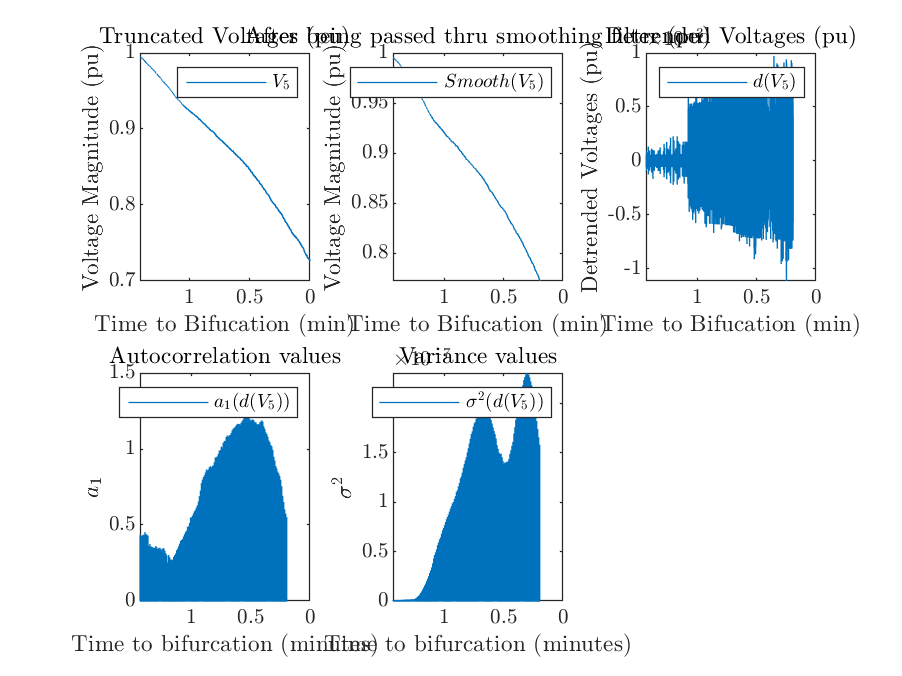


set(gcf, 'PaperSize', [24 12]); %set the paper size to what you want  
print(imagePdfName,'-dpdf', '-fillpage') % then print it

#### Estimate Spectral Power Density

% figure('Name', 'Welch Spectral Estimate of Bus Voltages.')
% [pxx, f] = pwelch(voltsTruncatedDetrendedArr(:, busesToPlot), 'psd');
% plot(f,pxx)